# standardize card image

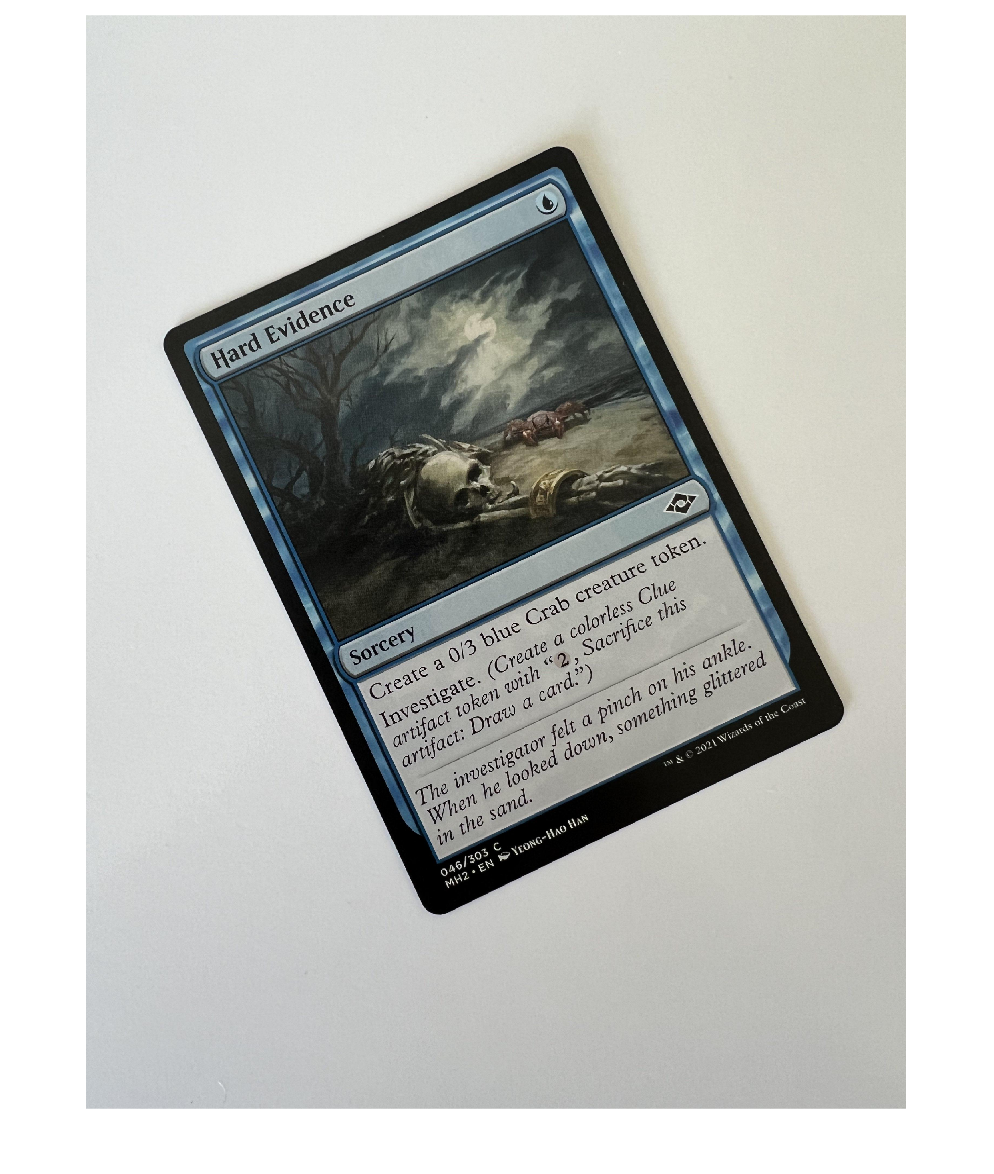

realImg = imread("hard_evidecne_rotated.jpg");
figure;
imshow(realImg);

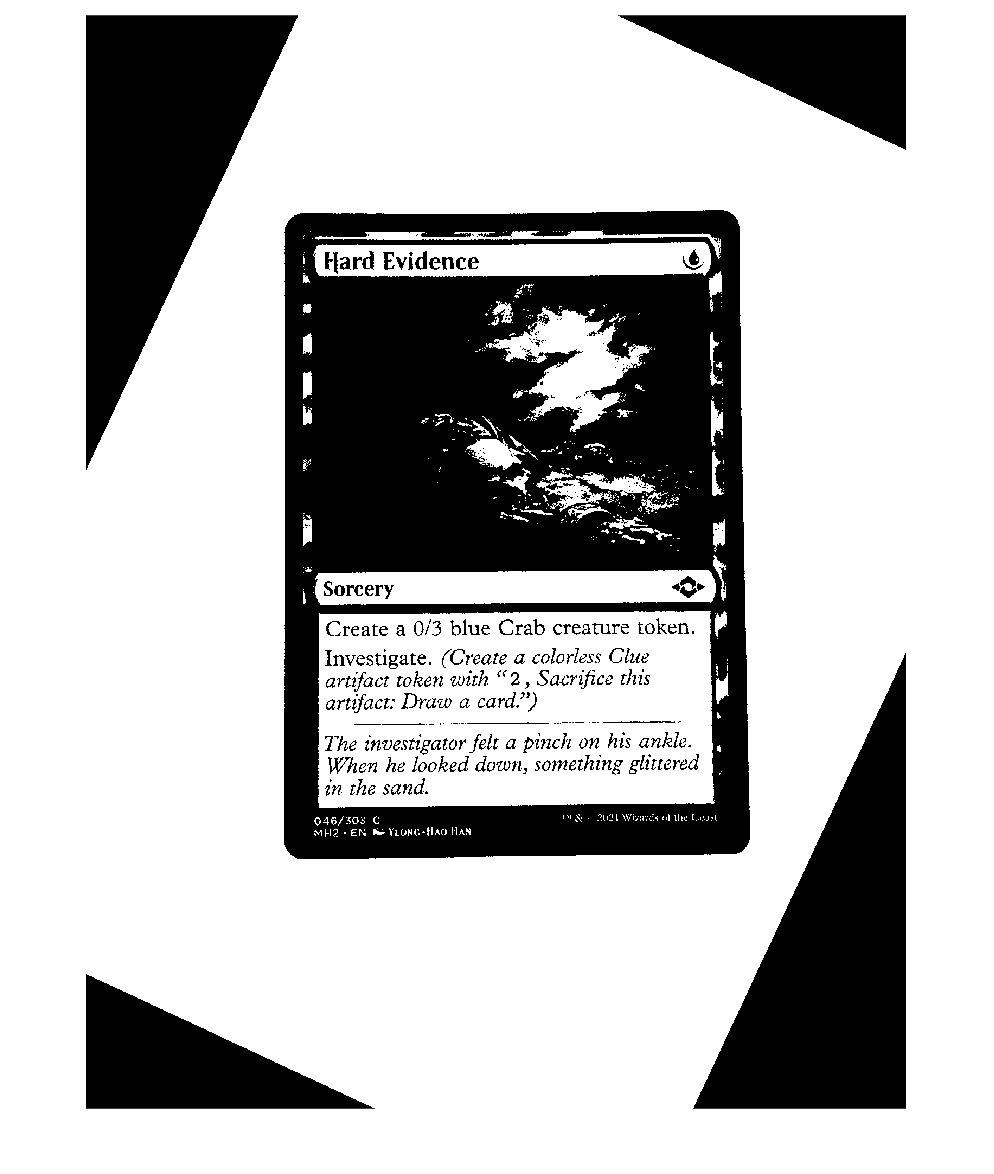


realImg = rgb2gray(realImg);
realImg = imbinarize(realImg,graythresh(realImg));

[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle)-90,'bilinear','crop');
%angs = 
%rotated_image = imrotate(testTop, avg_angle);

figure;
imshow(corrected);

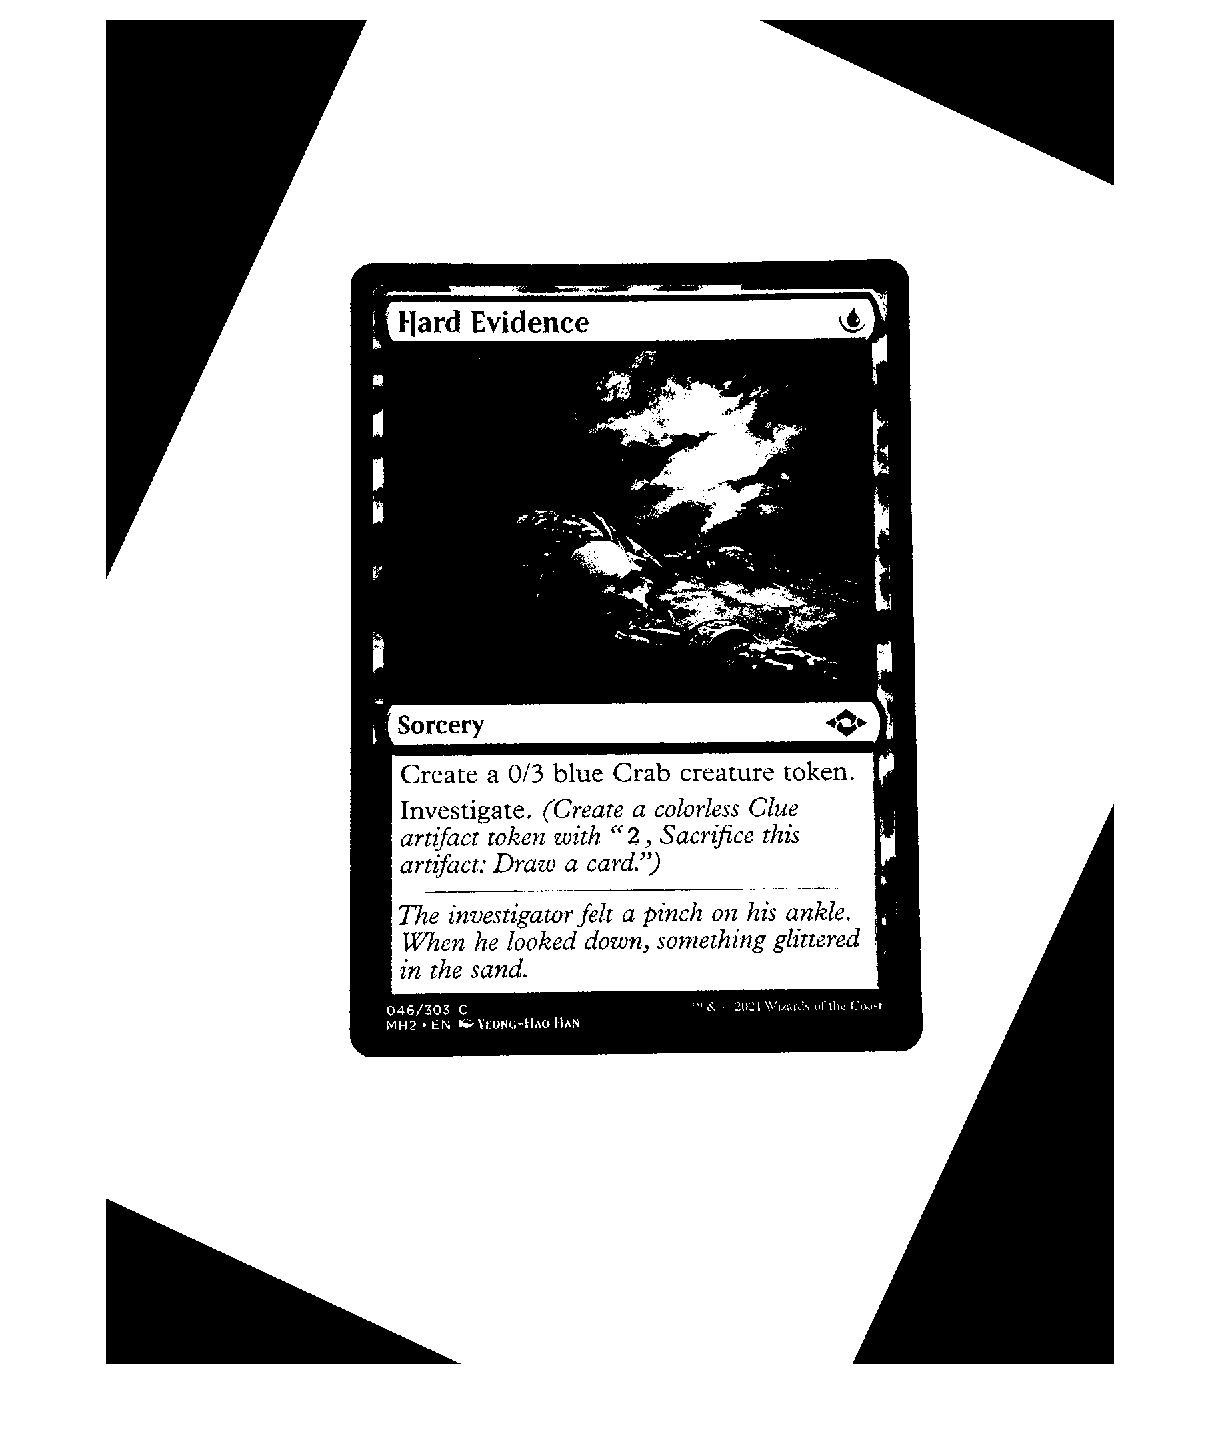

J = 2367×1719 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0

testRect = 1.0e+03 *

    0.7295    0.7385    1.7190    2.3670



[r,c] = size(corrected);

[J,testRect] = imcrop(corrected)

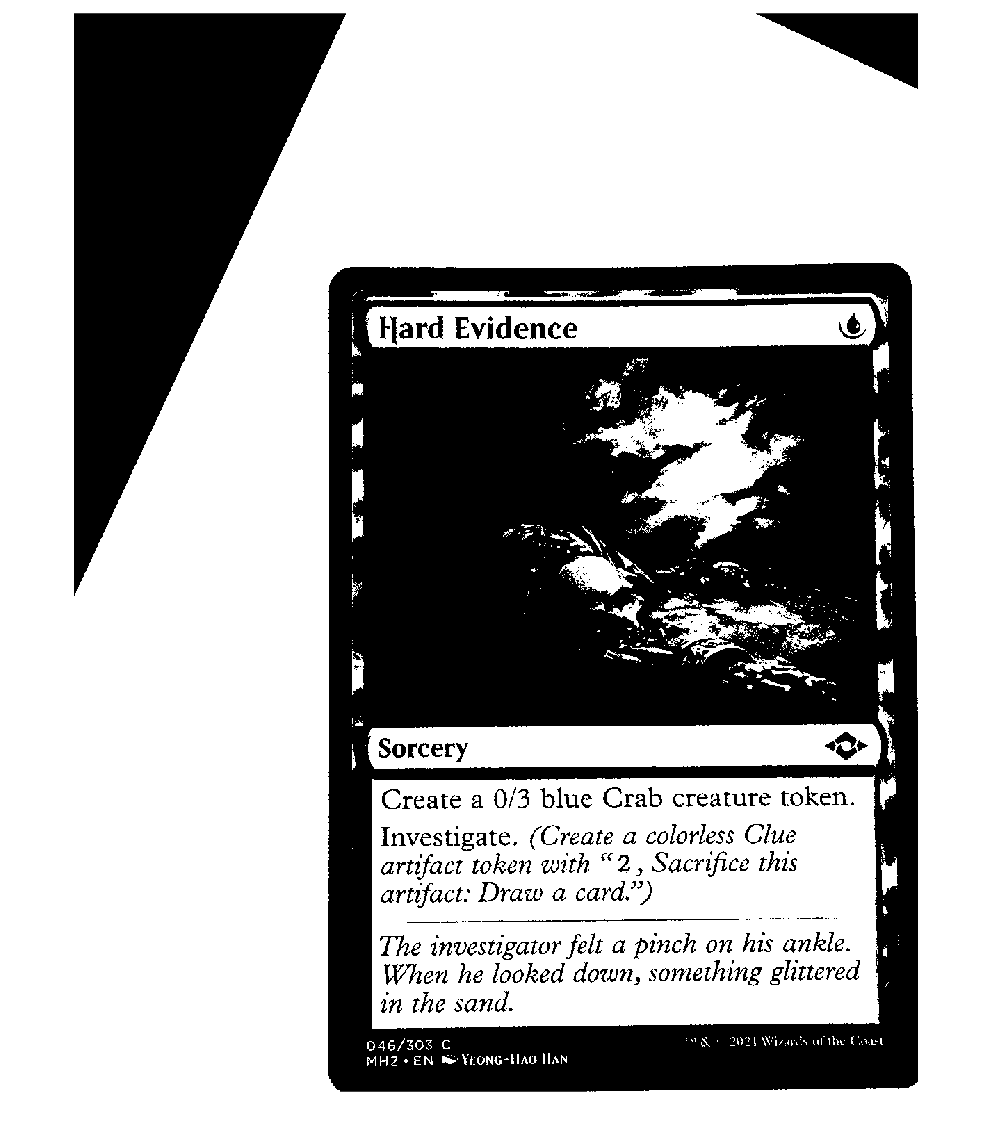


northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

cropRect = [1 1 eastmost southmost];
croppedImg = imcrop(corrected,cropRect);
[r1, c1] = size(croppedImg);
crotRect2 = [westmost northmost c1 r1];
croppedImg = imcrop(croppedImg,cropRect);
figure;
imshow(croppedImg);

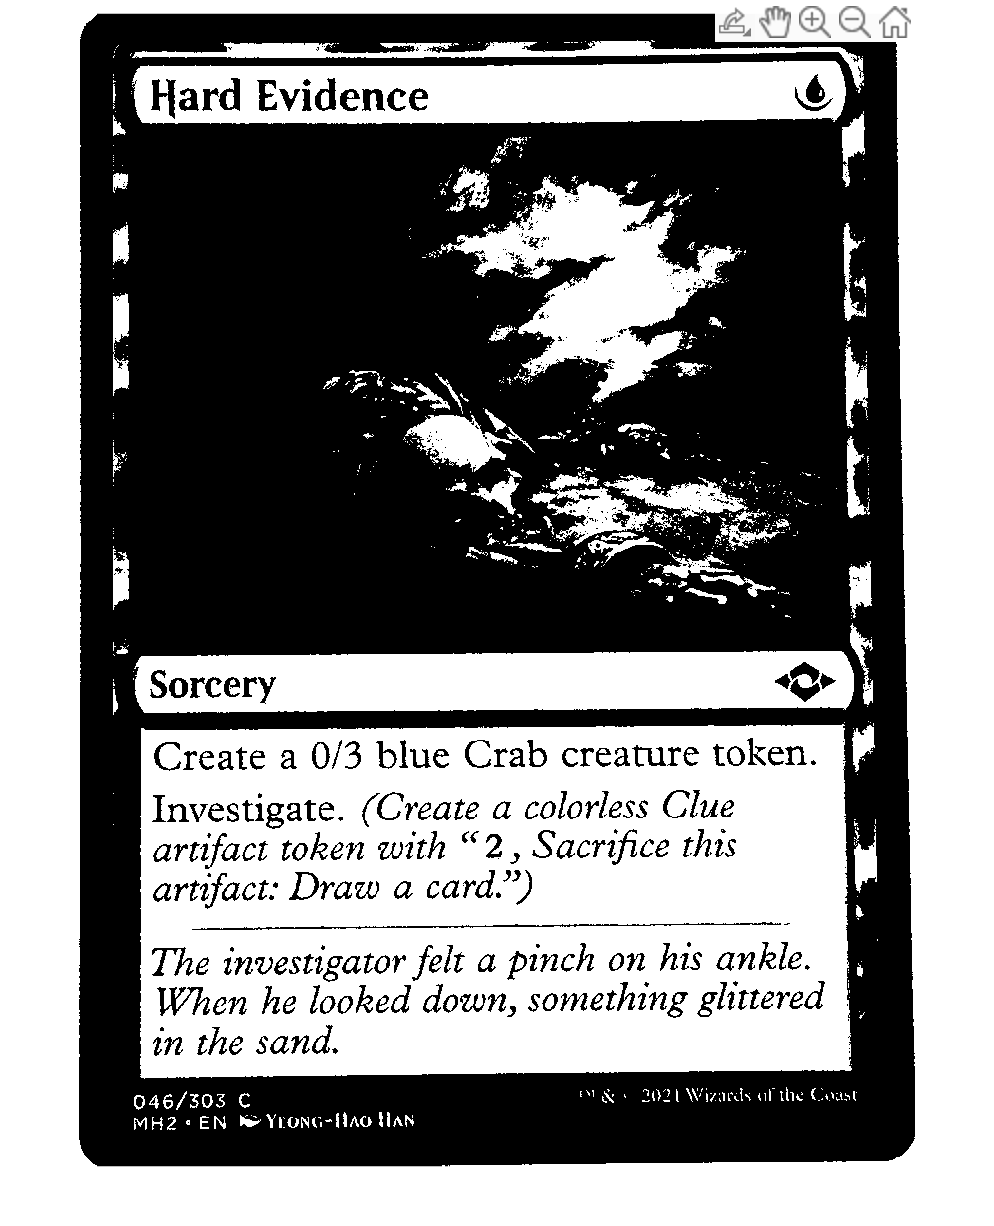


djgidj = imcrop(corrected,testRect);
imshow(djgidj);






% OCR test
% text = ocr(realImg);
% disp(text.Text);

%


%

% get
test = imread("https://cards.scryfall.io/art_crop/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");

% queries
% color
% text

## crop and segment


img = imread("https://cards.scryfall.io/normal/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");
hardRect = [18.51   21.51	111.98	88.98];
figure;
%imshow(img);